# Hilbert Matrices and Their Inverses

This example shows how to compute the inverse of a Hilbert matrix using Symbolic Math Toolbox™. 

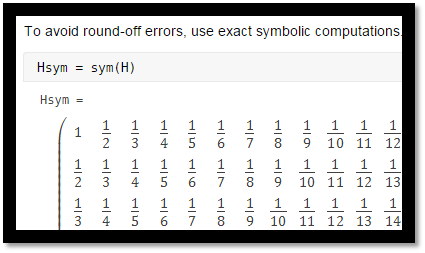

        **Definition** : A Hilbert matrix is a square matrix with entries being the unit fraction.  $H_{ij}=\frac{1}{i+j-1}$.  For example, the `3x3` Hilbert matrix is  $H = \left[ \begin{array}{c|c|c} 
  1 & \frac{1}{2} & \frac{1}{3} \\
  \frac{1}{2} & \frac{1}{3} & \frac{1}{4}\\
  \frac{1}{3} & \frac{1}{4} & \frac{1}{5}
 \end{array}
\right]$

 Symbolic computations give accurate results for these ill-conditioned matrices, while purely numerical methods fail.

Create a 20-by-20 numeric Hilbert matrix.

H = hilb(20);

Find the condition number of this matrix. Hilbert matrices are ill-conditioned, meaning that they have large condition numbers indicating that such matrices are nearly singular. Note that computing condition numbers is also prone to numeric errors.

cond(H)

Therefore, inverting Hilbert matrices is numerically unstable. When you compute a matrix inverse, `H*inv(H)` must return an identity matrix or a matrix close to the identity matrix within some error margin.

First, compute the inverse of `H` by using the `inv` function. A warning is thrown due to the numerical instability.

H*inv(H)

Now, use the MATLAB® `invhilb` function that offers better accuracy for Hilbert matrices. This function finds exact inverses of Hilbert matrices up to 15-by-15. For a 20-by-20 Hilbert matrix, `invhilb` finds the approximation of the matrix inverse.

H*invhilb(20)

To avoid round-off errors, use exact symbolic computations. For this, create the symbolic Hilbert matrix.

Hsym = sym(H)

Get the value of the condition number. It has been derived by symbolic methods and is free of numerical errors. 

vpa(cond(Hsym))

Although its condition number is large, you can compute the exact inverse of the matrix.

Hsym*inv(Hsym)

*Copyright 2014-2016 The MathWorks, Inc.*